# ECEN 611 Homework 4: Gap Function and Mutual Inductance for Salient Pole Rotor 

`Shuxuan Chen | 132006082 | Fall 2024`

## Problem 3 

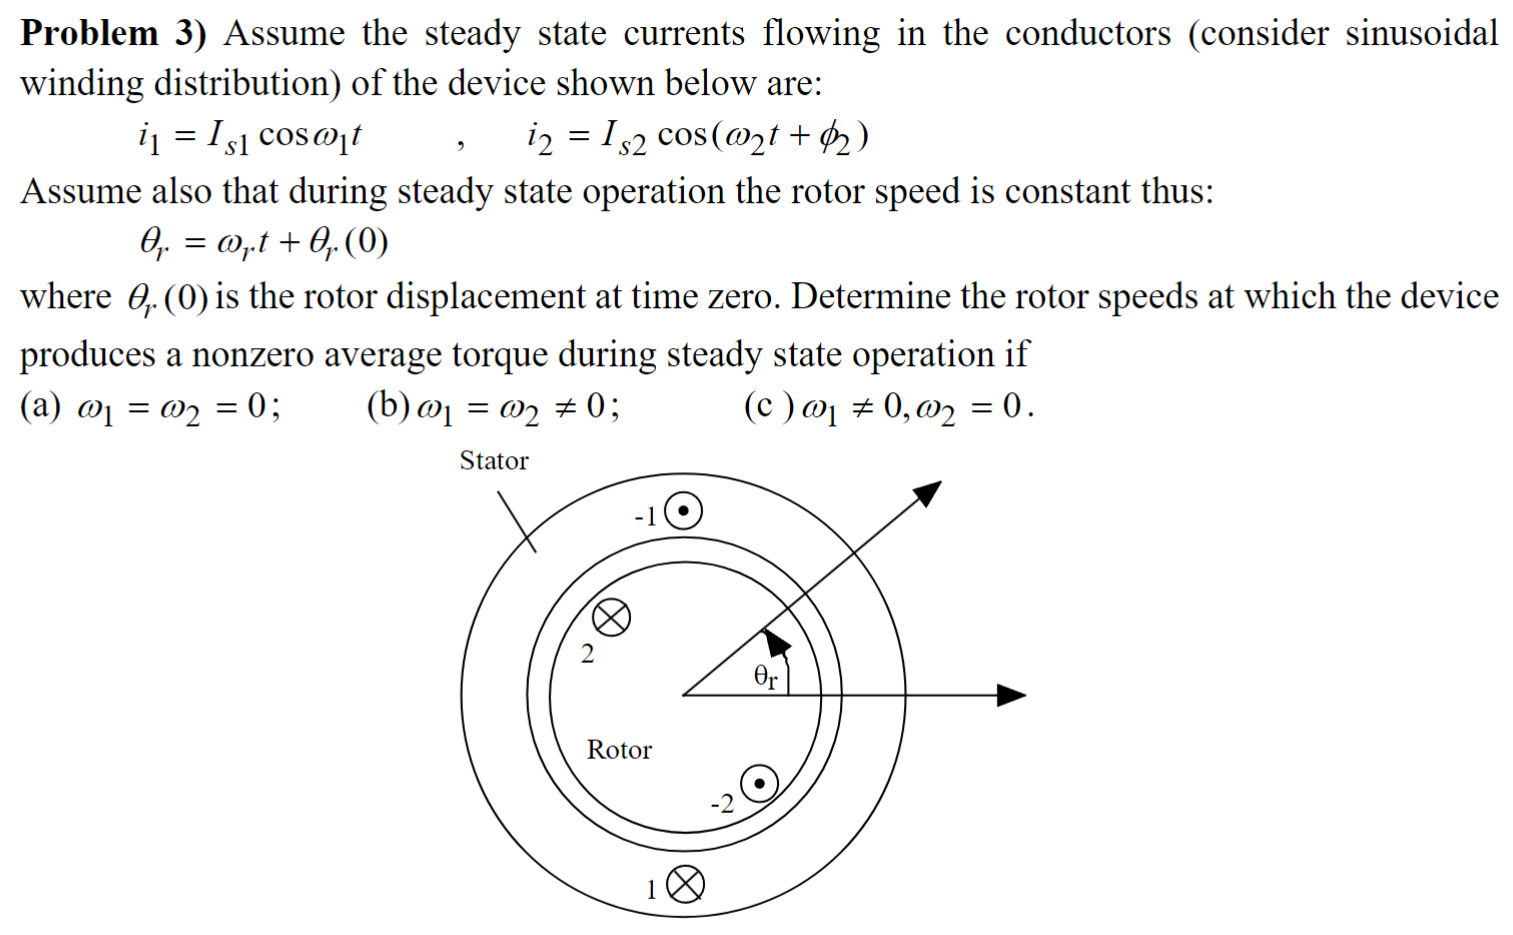

syms I positive real 
syms N_s 

syms phi 
syms theta_r 
assume( 0 <= theta_r <= 2*pi )

NS = 1;

T = 2*pi;

digits(4)

### Stator Counting & Winding Function 

statorCountingFunction(phi) = piecewise( ...
    0 <= phi < pi/2, 0, ...
    pi/2 <= phi < 3/2*pi, -N_s, ...
    3/2*pi <= phi < T, 0 ...
);

disp("Original Stator Counting Function φ ∈ [0 T] :")

Original Stator Counting Function φ ∈ [0 T] :


disp(statorCountingFunction(phi))

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi \in \left[0,\frac{\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[\frac{\pi }{2},\frac{3\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[\frac{3\,\pi }{2},2\,\pi \right) \end{array}\right.$$


statorCountingFunction_ext(phi) = piecewise( ...
    -2*T <= phi < -T, statorCountingFunction(phi+2*T), ...
    -T <= phi < 0, statorCountingFunction(phi+T), ...
    0 <= phi < T, statorCountingFunction(phi), ...
    T <= phi <= 2*T, statorCountingFunction(phi-T) ...
);

disp("Extended Stator Counting Function φ ∈ [-2T 2T] :")

Extended Stator Counting Function φ ∈ [-2T 2T] :


disp(statorCountingFunction_ext(phi))

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi \in \left[-4\,\pi ,-\frac{7\,\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[-\frac{7\,\pi }{2},-\frac{5\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[-\frac{5\,\pi }{2},-\frac{3\,\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[-\frac{3\,\pi }{2},-\frac{\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[-\frac{\pi }{2},\frac{\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[\frac{\pi }{2},\frac{3\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[\frac{3\,\pi }{2},\frac{5\,\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[\frac{5\,\pi }{2},\frac{7\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[\frac{7\,\pi }{2},4\,\pi \right) \end{array}\right.$$


statorCountingFunction_ext_avg = 1/T * int(statorCountingFunction_ext, phi, [0 T]);
statorWindingFunction_ext(phi) = statorCountingFunction_ext - statorCountingFunction_ext_avg

$$statorWindingFunction\_ext(phi) = \left\{ \begin{array}{cl} \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-4\,\pi ,-\frac{7\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[-\frac{7\,\pi }{2},-\frac{5\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-\frac{5\,\pi }{2},-\frac{3\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[-\frac{3\,\pi }{2},-\frac{\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-\frac{\pi }{2},\frac{\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[\frac{\pi }{2},\frac{3\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[\frac{3\,\pi }{2},\frac{5\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[\frac{5\,\pi }{2},\frac{7\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[\frac{7\,\pi }{2},4\,\pi \right) \end{array}\right.$$

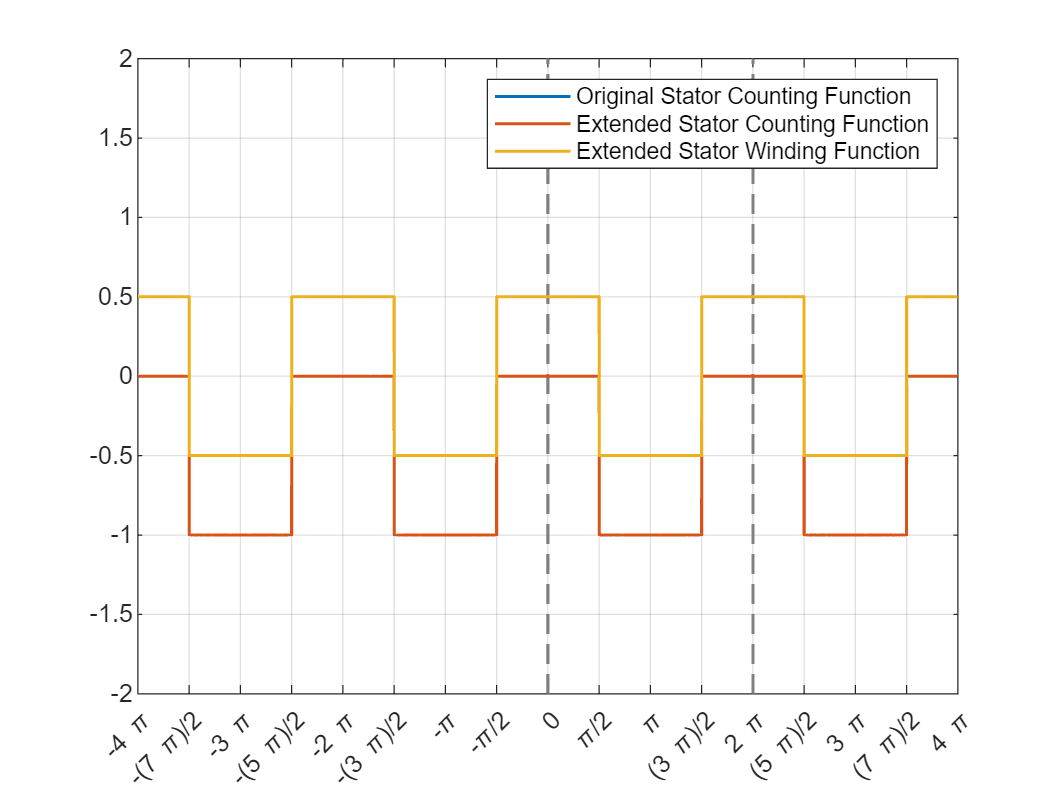


figure 
fplot(subs(statorCountingFunction(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Original Stator Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(statorCountingFunction_ext(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Extended Stator Counting Function", ...
    "LineWidth", 1.2)
fplot(subs(statorWindingFunction_ext(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Extended Stator Winding Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-2 2])
grid on  
legend 

ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Rotor Counting & Winding Function 

syms N_r 
NR = 1;

turnsRotorNum = [0     1    -1    0 ] * N_r;   % number of turns at each location: replace Nt with 1 for simplicity  
turnsRotorPhi = [0   T/4   T/2  T/4 ];  % angle of each location

turnsRotorNumLevel = cumsum(turnsRotorNum)

$$turnsRotorNumLevel = \left(\begin{array}{cccc} 0 & N_{r} & 0 & 0 \end{array}\right)$$


rotor_winding_turning_phi = theta_r + cumsum(turnsRotorPhi)

$$rotor\_winding\_turning\_phi = \left(\begin{array}{cccc} \theta_{r} & \theta_{r}+\frac{\pi }{2} & \theta_{r}+\frac{3\,\pi }{2} & \theta_{r}+2\,\pi \end{array}\right)$$

rotorCountingFunction(phi) = turnsRotorNumLevel(1);

phiReference = 0;

for k = 1:length(rotor_winding_turning_phi)-1
    
    thisPhi = rotor_winding_turning_phi(k);
    nextPhi = rotor_winding_turning_phi(k+1);

    rotorCountingFunction(phi) = piecewise(thisPhi <= phi < nextPhi, turnsRotorNumLevel(k), ...
                                           phiReference <= phi < thisPhi, rotorCountingFunction);
end 

#### Original Rotor Counting Function φ ∈ [θr θr+T]

disp("Original Rotor Counting Function: ");

Original Rotor Counting Function: 


disp(rotorCountingFunction(phi));

$$\left\{ \begin{array}{cl} 0 & \text{ if }2\,\theta_{r}+3\,\pi \leq 2\,\varphi \wedge \varphi <\theta_{r}+2\,\pi \\ N_{r} & \text{ if }2\,\varphi <2\,\theta_{r}+3\,\pi \wedge 2\,\theta_{r}+\pi \leq 2\,\varphi \\ 0 & \text{ if }2\,\varphi <2\,\theta_{r}+\pi \wedge 0\leq \varphi \wedge \left(\varphi <\theta_{r}\vee \left(\theta_{r}\leq \varphi \wedge 2\,\varphi <2\,\theta_{r}+\pi \right)\right) \end{array}\right.$$

#### Extended Rotor Counting Function φ ∈ [θr-2T θr+2T]

rotorCountingFunction_ext(phi) = piecewise( ...
    theta_r - 2*T <= phi < theta_r - T, rotorCountingFunction(phi+2*T), ...
    theta_r - T <= phi < theta_r,       rotorCountingFunction(phi+T), ...
    theta_r <= phi < theta_r + T,       rotorCountingFunction(phi), ...
    theta_r + T <= phi < theta_r + 2*T, rotorCountingFunction(phi-T) ...
)

$$rotorCountingFunction\_ext(phi) = \left\{ \begin{array}{cl} 0 & \text{ if }2\,\theta_{r}\leq 2\,\varphi +5\,\pi \wedge \varphi +2\,\pi <\theta_{r}\\ N_{r} & \text{ if }2\,\varphi +5\,\pi <2\,\theta_{r}\wedge 2\,\theta_{r}\leq 2\,\varphi +7\,\pi \wedge \varphi \in \mathbb{R}\\ 0 & \text{ if }\left(\varphi <\theta_{r}\wedge 2\,\theta_{r}\leq 2\,\varphi +\pi \right)\vee \left(2\,\varphi +7\,\pi <2\,\theta_{r}\wedge \theta_{r}\leq \varphi +4\,\pi \wedge \varphi \in \mathbb{R}\wedge \left(\varphi +4\,\pi <\theta_{r}\vee \left(2\,\varphi +7\,\pi <2\,\theta_{r}\wedge \theta_{r}\leq \varphi +4\,\pi \right)\right)\right)\\ N_{r} & \text{ if }2\,\theta_{r}\leq 2\,\varphi +3\,\pi \wedge \varphi \in \mathbb{R}\wedge 2\,\varphi +\pi <2\,\theta_{r}\\ 0 & \text{ if }\left(2\,\theta_{r}+3\,\pi \leq 2\,\varphi \wedge \varphi <\theta_{r}+2\,\pi \right)\vee \left(2\,\varphi +3\,\pi <2\,\theta_{r}\wedge \theta_{r}\leq \varphi +2\,\pi \wedge \varphi \in \mathbb{R}\wedge \left(\varphi +2\,\pi <\theta_{r}\vee \left(2\,\varphi +3\,\pi <2\,\theta_{r}\wedge \theta_{r}\leq \varphi +2\,\pi \right)\right)\right)\\ N_{r} & \text{ if }2\,\varphi <2\,\theta_{r}+3\,\pi \wedge \varphi \in \mathbb{R}\wedge 2\,\theta_{r}+\pi \leq 2\,\varphi \\ 0 & \text{ if }\left(2\,\theta_{r}+7\,\pi \leq 2\,\varphi \wedge \varphi <\theta_{r}+4\,\pi \right)\vee \left(\theta_{r}\leq \varphi \wedge 2\,\varphi <2\,\theta_{r}+\pi \wedge \left(\varphi <\theta_{r}\vee \left(\theta_{r}\leq \varphi \wedge 2\,\varphi <2\,\theta_{r}+\pi \right)\right)\right)\\ N_{r} & \text{ if }2\,\varphi <2\,\theta_{r}+7\,\pi \wedge 2\,\theta_{r}+5\,\pi \leq 2\,\varphi \wedge \varphi \in \mathbb{R}\\ 0 & \text{ if }2\,\varphi <2\,\theta_{r}+5\,\pi \wedge \theta_{r}+2\,\pi \leq \varphi \wedge \varphi \in \mathbb{R}\wedge \left(\varphi <\theta_{r}+2\,\pi \vee \left(2\,\varphi <2\,\theta_{r}+5\,\pi \wedge \theta_{r}+2\,\pi \leq \varphi \right)\right) \end{array}\right.$$

#### Extended Rotor Winding Function φ ∈ [θr-2T θr+2T]

% assume( theta < T )
rotorCountingFunction_ext_avg = 1/T * int(rotorCountingFunction_ext, phi, [0 T]);
rotorWindingFunction_ext = rotorCountingFunction_ext - rotorCountingFunction_ext_avg

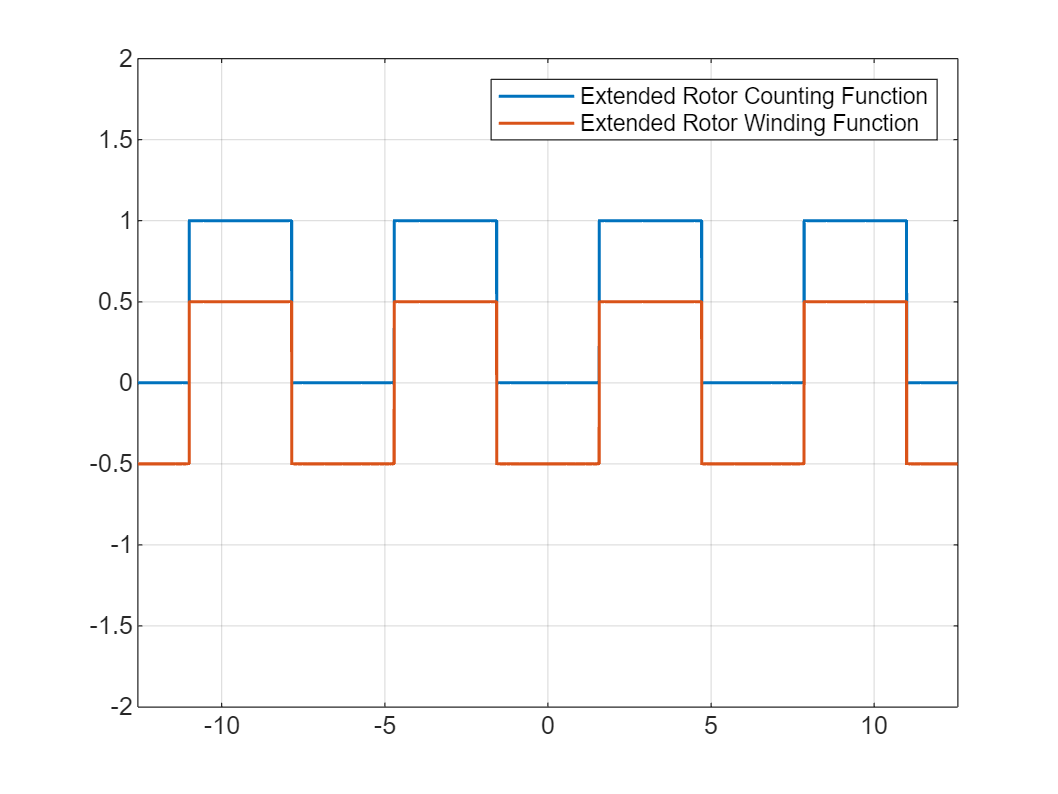


figure 
fplot(subs(rotorCountingFunction_ext(phi),[theta_r N_r], [0 NR]), [-2*T 2*T], ...
    "DisplayName", "Extended Rotor Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(rotorWindingFunction_ext(phi),[theta_r N_r], [0 NR]), [-2*T 2*T], ...
    "DisplayName", "Extended Rotor Winding Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-2 2])
grid on  
legend 

### Stator Winding Magnetizing Inductance

syms mu_o r l g 
Lss = mu_o*r*l/g * int( statorWindingFunction_ext * statorWindingFunction_ext, ...
                     phi, [0 T]);

Lss_simplified = subs( simplify( vpa(Lss) ) )

$$Lss\_simplified = \frac{1.571\,{N_{s}}^{2}\,l\,\mu_{o}\,r}{g}$$

% Lss_simplified = subs( simplify( vpa(Lss) ), N_s^2*l*mu_o*r/g, 1 )

### Rotor Winding Magnetizing Inductance

syms mu_o r l g 

Lrr_integrand = subs(rotorWindingFunction_ext * rotorWindingFunction_ext, theta_r, 0:T/8:T);

tic
Lrr = vpa( simplify( mu_o*r*l/g * int( Lrr_integrand, phi, [0 T] ) ) )

$$Lrr = \left(\begin{array}{ccccccccc} \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} \end{array}\right)$$

toc 

Elapsed time is 1.354199 seconds.



Lrr = Lrr(1)

$$Lrr = \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g}$$

Rotor Winding Magnetizing Inductance is independent of rotor angle.

### Stator-Rotor Winding Mutual Inductance 

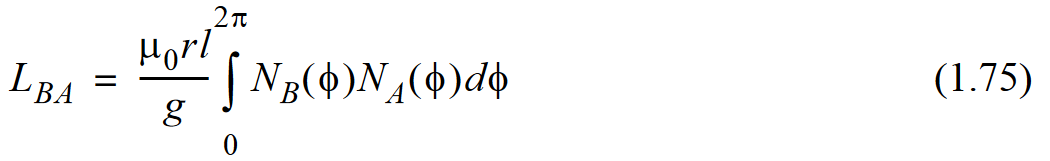

Lsr_integrand = simplify( vpa( rotorWindingFunction_ext * statorWindingFunction_ext ) )

% Lsr_integrand = vpa( rotorWindingFunction_ext * statorWindingFunction_ext )


tic
Lsr = mu_o*r*l/g * int(Lsr_integrand, phi, [0 T]); 
toc

Elapsed time is 22.924358 seconds.



Lsr_simplified = subs( simplify( vpa(Lsr) ), N_r*N_s*l*mu_o*r/g, 1 )

$$Lsr\_simplified = \left\{ \begin{array}{cl} -1.571 & \text{ if }\theta_{r}=0\\ -9.183e-7 & \text{ if }\theta_{r}=4.712\\ -3.673e-6 & \text{ if }\theta_{r}=4.712\\ 1.571 & \text{ if }\theta_{r}=3.142\\ 1.571 & \text{ if }\theta_{r}=3.142\\ 2.356-0.5\,\theta_{r} & \text{ if }\theta_{r}\in \left(4.712,4.712\right]\\ 0.75\,\theta_{r}-1.178 & \text{ if }\theta_{r}\in \left[1.571,1.571\right]\\ 1.571 & \text{ if }\theta_{r}\in \left(3.142,3.142\right)\\ 4.712-1.0\,\theta_{r} & \text{ if }4.712<\theta_{r}\vee \theta_{r}\in \left(3.142,4.712\right)\\ 1.0\,\theta_{r}-1.571 & \text{ if }\theta_{r}\in \left(0.0,1.571\right)\vee \theta_{r}\in \left(1.571,3.142\right) \end{array}\right.$$

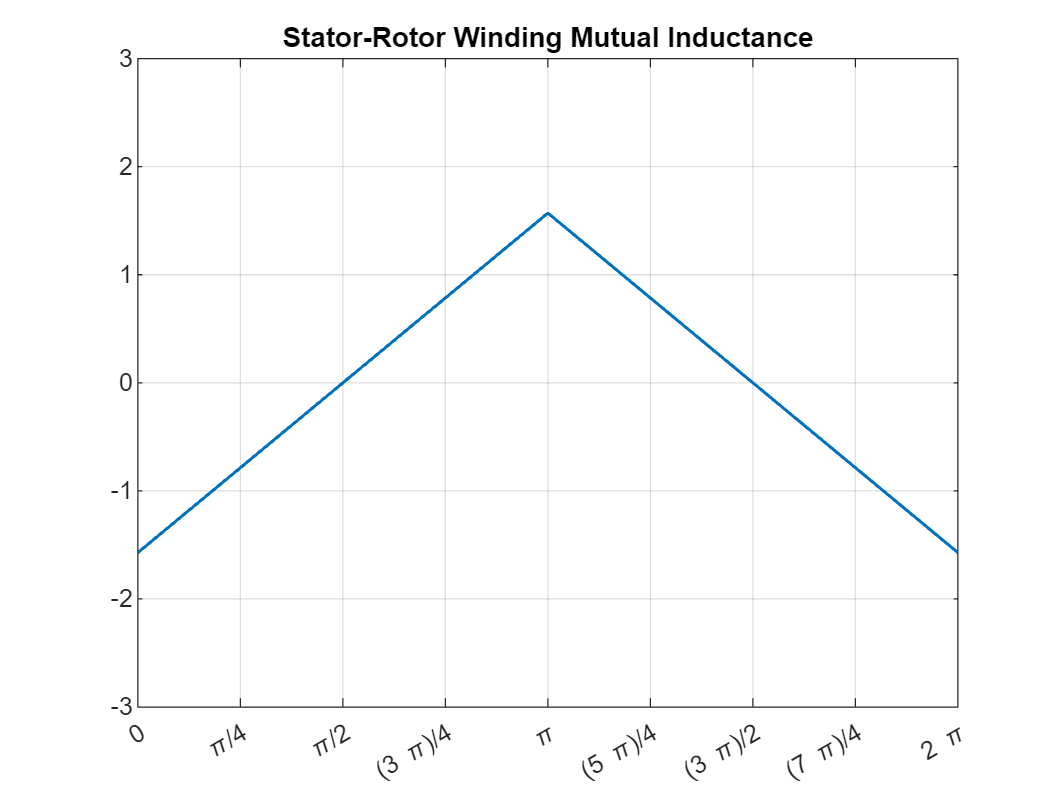

figure 

fplot(Lsr_simplified, [0 T], ...
    "LineWidth", 1.2)
ylim([-3 3])
grid on  
title("Stator-Rotor Winding Mutual Inductance")

ax = gca;
S = sym(ax.XLim(1):pi/4:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

% Fourier Series of Lsr 
digits(4)

a0 = vpa( (1/T) * int( Lsr_simplified, theta_r, [0 T], ...
    'IgnoreSpecialCases', true) )

$$a0 = 6.047e-5$$

syms n 

an = (2/T) * int( Lsr_simplified * cos(n * theta_r), theta_r, [0 T]);
bn = (2/T) * int( Lsr_simplified * sin(n * theta_r), theta_r, [0 T]);

orderOfHarmonics = 1:13;
an_13 = vpa( simplify( subs(an, n, orderOfHarmonics) ) );
bn_13 = vpa( simplify( subs(bn, n, orderOfHarmonics) ) );

tolerance = 1e-4;

an_13(abs(an_13) < tolerance) = 0

$$an\_13 = \left(\begin{array}{ccccccccccccc} -1.273 & 0 & -0.1415 & 0 & -0.05093 & 0 & -0.02599 & 0 & -0.01572 & 0 & -0.01052 & 0 & -0.007533 \end{array}\right)$$

bn_13(abs(bn_13) < tolerance) = 0

$$bn\_13 = \left(\begin{array}{ccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


Lsr_fourier_filtered = a0 + ...
    sum(an_13 .* cos(orderOfHarmonics .* theta_r) + ...
        bn_13 .* sin(orderOfHarmonics .* theta_r))

$$Lsr\_fourier\_filtered = 6.047e-5-0.05093\,\cos\left(5\,\theta_{r}\right)-0.02599\,\cos\left(7\,\theta_{r}\right)-0.01572\,\cos\left(9\,\theta_{r}\right)-0.01052\,\cos\left(11\,\theta_{r}\right)-0.007533\,\cos\left(13\,\theta_{r}\right)-1.273\,\cos\left(\theta_{r}\right)-0.1415\,\cos\left(3\,\theta_{r}\right)$$

Lsr_fourier_approx = an_13(1) * cos(orderOfHarmonics(1) * theta_r)

$$Lsr\_fourier\_approx = -1.273\,\cos\left(\theta_{r}\right)$$

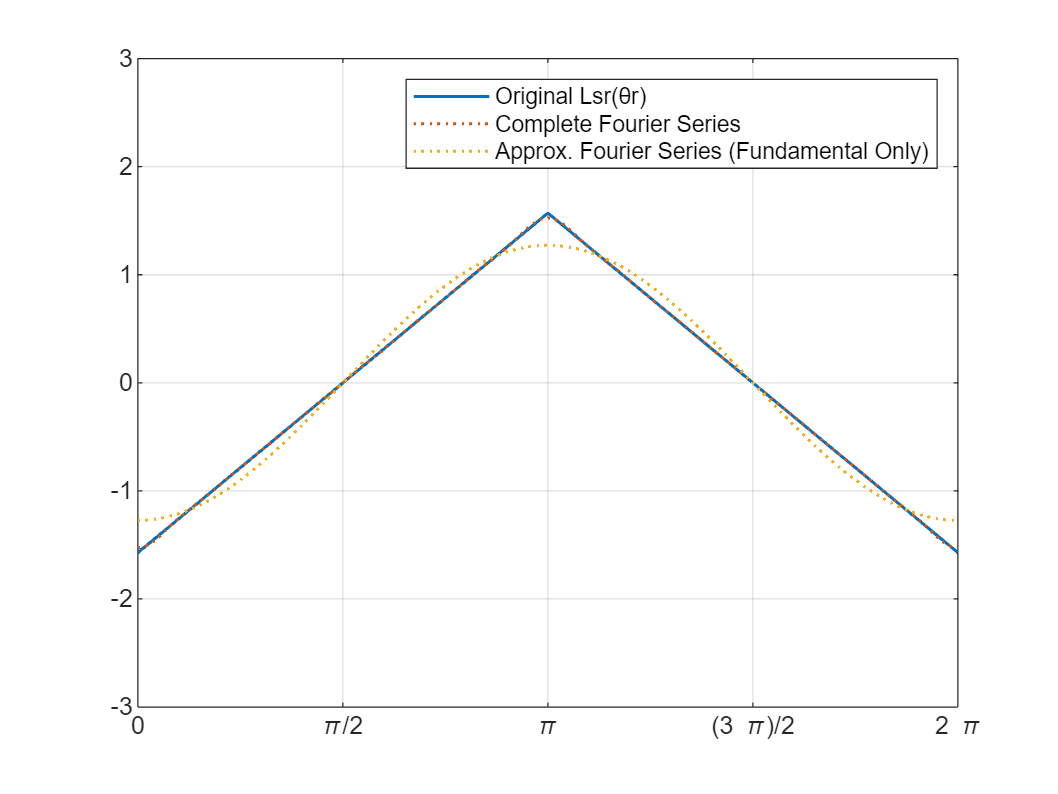


figure 
fplot(Lsr_simplified, [0 T], ...
      "DisplayName", "Original Lsr(θr)", ...
      "LineWidth", 1.2)
hold on 
fplot(Lsr_fourier_filtered, [0 T], ...
      "DisplayName", "Complete Fourier Series", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
fplot(Lsr_fourier_approx, [0 T], ...
      "DisplayName", "Approx. Fourier Series (Fundamental Only)", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([-3 3])
grid on 
legend 

ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Torque Production

syms I_s1 omega_1 I_s2 omega_2 
syms t 
syms phi_2 omega_r theta_r 

magnitude = [I_s1 I_s2];
omega = [omega_1 omega_2];
angle = [ omega_1*t omega_2*t + phi_2 ];
current = magnitude .* cos(angle);
i1 = current(1)

$$i1 = I_{\mathrm{s1}}\,\cos\left(\omega_{1}\,t\right)$$

i2 = current(2)

$$i2 = I_{\mathrm{s2}}\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)$$

#### Reluctance Torque 

reluctanceTorque = 1/2 * (i1^2*diff(Lss,theta_r) + i2^2*diff(Lrr,theta_r))

$$reluctanceTorque = 0.0$$

#### Alignment Torque 

disp(Lsr_fourier_approx)

$$-1.273\,\cos\left(\theta_{r}\right)$$

alignmentTorque = i1 * i2 * diff(Lsr_fourier_approx, theta_r)

$$alignmentTorque = 1.273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\cos\left(\omega_{1}\,t\right)\,\sin\left(\theta_{r}\right)$$

#### Total Torque

totalTorque = simplify( reluctanceTorque + alignmentTorque )

$$totalTorque = 1.273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\cos\left(\omega_{1}\,t\right)\,\sin\left(\theta_{r}\right)$$

syms omega_r omega_r0 omega_m delta
totalTorque = subs(totalTorque, theta_r, omega_m*t + delta)

$$totalTorque = 1.273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\sin\left(\delta +\omega_{m}\,t\right)\,\cos\left(\omega_{1}\,t\right)$$

 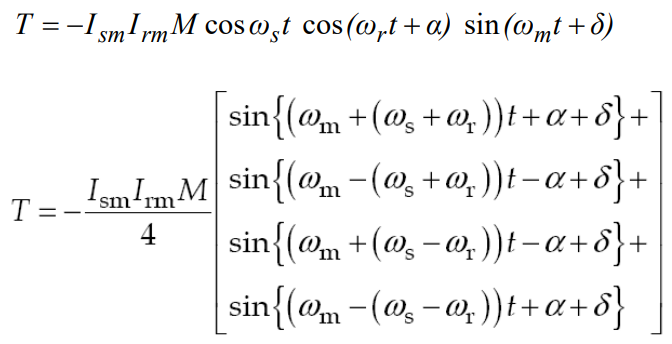

Given the transformation above, it is clear that the average value of each term is zero unless the coefficient of t is zero. 

Unfortunately, MATLAB seems incapable of performing such a transformation using Product-to-Sum Trigonometric Identities

cos(A)cos(B)=1/2�[cos(A+B)+cos(A−B)]

sin(A)cos(B)=1/2�[sin(A+B)+sin(A−B)]

as you can see if you uncomment the following code.

% expanded_totalTorque = expand(totalTorque)
% rewritten_totalTorque = rewrite(expanded_totalTorque, 'sin')
% simplified_totalTorque = simplify(rewritten_totalTorque)
% final_totalTorque = expand(simplified_totalTorque)

Although, MATLAB can do this the other way round:

syms A B
ccSum = 1/2*(cos(A+B)+cos(A-B))

$$ccSum = \frac{\cos\left(A+B\right)}{2}+\frac{\cos\left(A-B\right)}{2}$$

ccProduct = simplify(ccSum)

$$ccProduct = \cos\left(A\right)\,\cos\left(B\right)$$

ssSum = 1/2*(sin(A+B)+sin(A-B))

$$ssSum = \frac{\sin\left(A+B\right)}{2}+\frac{\sin\left(A-B\right)}{2}$$

ssProduct = simplify(ssSum)

$$ssProduct = \cos\left(B\right)\,\sin\left(A\right)$$

Well, let us realize it manually:

% Define the four sine terms
term1 = sin((omega_m + (omega_1 + omega_2))*t + phi_2 + delta);
term2 = sin((omega_m - (omega_1 + omega_2))*t - phi_2 + delta);
term3 = sin((omega_m + (omega_1 - omega_2))*t - phi_2 + delta);
term4 = sin((omega_m - (omega_1 - omega_2))*t + phi_2 + delta);

% Combine them with the coefficient
totalTorque_manual = (1.273 * I_s1 * I_s2 / 4) * (term1 + term2 + term3 + term4);

% Simplify and verify 
simplify(vpa(totalTorque_manual))

$$ans = 1.273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\sin\left(\delta +\omega_{m}\,t\right)\,\cos\left(\omega_{1}\,t\right)$$

vpa(totalTorque)

$$ans = 1.273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\sin\left(\delta +\omega_{m}\,t\right)\,\cos\left(\omega_{1}\,t\right)$$

### Rotor Speed ωr

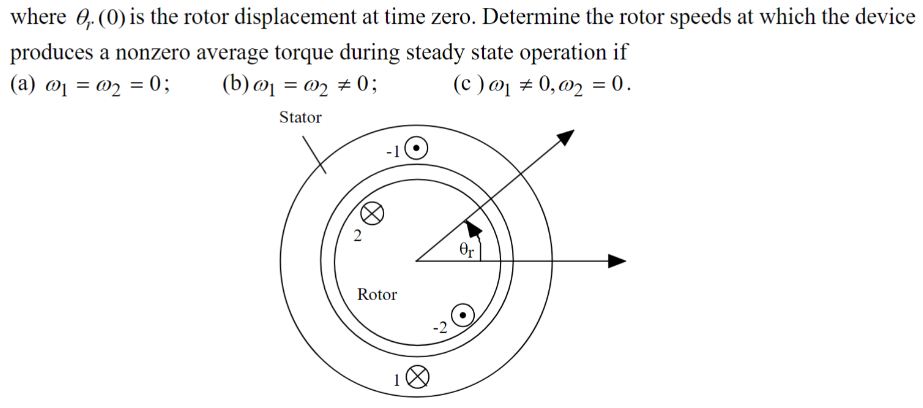

Determine the rotor speeds at which the device produces a nonzero average torque during steady state operation if

#### (a) When ω1 = ω2 = 0

DC current supply. Single phase machine.

totalTorque_case_a = subs(totalTorque_manual, omega, [0 0])

$$totalTorque\_case\_a = \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\left(2\,\sin\left(\delta -\varphi_{2}+\omega_{m}\,t\right)+2\,\sin\left(\delta +\varphi_{2}+\omega_{m}\,t\right)\right)}{4000}$$

totalTorque_case_a = subs(totalTorque_case_a, omega_m, 0)

$$totalTorque\_case\_a = \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\left(2\,\sin\left(\delta -\varphi_{2}\right)+2\,\sin\left(\delta +\varphi_{2}\right)\right)}{4000}$$

% totalTorque_case_a_avg = 1/T * int( ...
%     subs(totalTorque_case_a, omega_r*t, theta_r), ...
%     theta_r, [0 T])

Only when $\omega_m =0$ can the device produce a nonzero average torque. 

#### (b) When ω1 = ω2 ≠ 0

Let's assume ω1 = ω2 = ω1

totalTorque_case_b = subs(totalTorque_manual, omega(2), omega_1)

$$totalTorque\_case\_b = \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\left(\sin\left(\delta +\varphi_{2}+t\,\left(2\,\omega_{1}+\omega_{m}\right)\right)+\sin\left(\delta -\varphi_{2}+\omega_{m}\,t\right)-\sin\left(\varphi_{2}-\delta +t\,\left(2\,\omega_{1}-\omega_{m}\right)\right)+\sin\left(\delta +\varphi_{2}+\omega_{m}\,t\right)\right)}{4000}$$

% totalTorque_case_b_avg = simplify( ...
%     expand( ...
%         vpa( 1/T * int(totalTorque_case_b, t, [0 T/omega_m]) ) ...
%     ) ...
% );

Either 


$$\begin{array}{l}
2\,\omega_1 +\omega_m =0\Rightarrow \omega_m =-2\omega_1 \;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{and}\;\\
\;\;\;\;\;\;\;\delta -\phi_2 \not= 0\Rightarrow \delta \not= \phi_2 \;
\end{array}$$
 

totalTorque_case_b_nonZero = simplify(subs(totalTorque_case_b, omega_m, 2*omega_1))

$$totalTorque\_case\_b\_nonZero = \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\left(\sin\left(\delta -\varphi_{2}\right)+\sin\left(\delta -\varphi_{2}+2\,\omega_{1}\,t\right)+\sin\left(\delta +\varphi_{2}+2\,\omega_{1}\,t\right)+\sin\left(\delta +\varphi_{2}+4\,\omega_{1}\,t\right)\right)}{4000}$$

or 


$$\begin{array}{l}
\omega_m =0\;\mathrm{and}\;\\
\delta \not= 0,\;\phi_2 \not= 0\;
\end{array}$$
 

totalTorque_case_b_nonZero = simplify(subs(totalTorque_case_b, omega_m, 0))

$$totalTorque\_case\_b\_nonZero = \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\sin\left(\delta \right)\,\left(\cos\left(\varphi_{2}+2\,\omega_{1}\,t\right)+\cos\left(\varphi_{2}\right)\right)}{2000}$$

will result in a non-zero torque.

#### (c) When ω1 ≠ 0, ω2 = 0

totalTorque_case_c = subs(totalTorque_manual, omega(2), 0)

$$totalTorque\_case\_c = \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\left(\sin\left(\delta -\varphi_{2}+t\,\left(\omega_{1}+\omega_{m}\right)\right)+\sin\left(\delta +\varphi_{2}-t\,\left(\omega_{1}-\omega_{m}\right)\right)-\sin\left(\varphi_{2}-\delta +t\,\left(\omega_{1}-\omega_{m}\right)\right)+\sin\left(\delta +\varphi_{2}+t\,\left(\omega_{1}+\omega_{m}\right)\right)\right)}{4000}$$

totalTorque_case_c_nonZero = subs(totalTorque_case_c, omega_m, [omega_1 -omega_1])

$$totalTorque\_case\_c\_nonZero = \left(\begin{array}{cc} \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\left(\sin\left(\delta -\varphi_{2}\right)+\sin\left(\delta -\varphi_{2}+2\,\omega_{1}\,t\right)+\sin\left(\delta +\varphi_{2}\right)+\sin\left(\delta +\varphi_{2}+2\,\omega_{1}\,t\right)\right)}{4000} & \frac{1273\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,\left(\sin\left(\delta -\varphi_{2}\right)-\sin\left(\varphi_{2}-\delta +2\,\omega_{1}\,t\right)+\sin\left(\delta +\varphi_{2}\right)+\sin\left(\delta +\varphi_{2}-2\,\omega_{1}\,t\right)\right)}{4000} \end{array}\right)$$

Only when $\omega_m =|\omega_1 |$ the device can produce a non-zero torque.